Load data files: 

bagSelect = rosbag('28-8-22-Experiment1-Logs/Experiment1-28-08-22-30-18.bag');
truth = sortrows(readmatrix('28-8-22-Experiment1-Logs/Experiment-2-Waypoint-Navigation-Truth.txt'));
% load('test1.mat'); 

World Transformation 

% Must match experiment initial pose 
setInitialPose = [0, 0, pi/2]; %[x, y, theta] w.r.t World 

Generate Figure Titles

experimentString = 'Experiment-2-Waypoint-Navigation'; 
if ~exist([strcat(experimentString, '-Figures')], 'dir')
   mkdir ([strcat(experimentString, '-Figures')]);
end

Process Sensor Streams 

% Capture data on /zlac8015d/encoder topic 
encoderLog = select(bagSelect, 'Topic','/zlac8015d/encoder');
cmdInputLot = select(bagSelect, 'Topic', '/zlac8015d/rpm');
voltageLog = select(bagSelect, 'Topic', '/amr/status/voltage');
currentLog = select(bagSelect, 'Topic', '/amr/status/current'); 
mapLog = select(bagSelect, 'Topic', '/slamware_ros_sdk_server_node/map');
poseLog = select(bagSelect, 'Topic', '/slamware_ros_sdk_server_node/odom');

% Read data 
encoderPlot = readMessages(encoderLog);
cmdInputPlot = readMessages(cmdInputLot); 
voltagePlot = readMessages(voltageLog);
currentPlot = readMessages(currentLog); 
mapPlot = readMessages(mapLog);
posePlot = readMessages(poseLog); 

% Determine vector length
[encoderLength,~] = size(encoderPlot);
[voltageLength,~] = size(voltagePlot); 
[currentLength,~] = size(currentPlot); 
[poseLength, ~] = size(posePlot); 
[mapLength, ~] = size(mapPlot); 

% Preallocate array sizes
leftEncoder = zeros(encoderLength,1);
rightEncoder = zeros(encoderLength,1);
leftRPM = zeros(encoderLength,1);
rightRPM = zeros(encoderLength,1); 
voltage = zeros(voltageLength, 1); 
current = zeros(currentLength, 1); 
lidarPose = zeros(poseLength, 1); 
robotPose = zeros(poseLength, 1); 

% Parse encoder data 
for i = 1:encoderLength
    leftEncoder(i,1) = encoderPlot{i}.Data(1,:);
    rightEncoder(i,1) = -encoderPlot{i}.Data(2,:);
    leftRPM(i,1) = encoderPlot{i}.Data(3,1); 
    rightRPM(i,1) = encoderPlot{i}.Data(4,1); 
end 

% Parse voltage data
for i = 1:voltageLength
    voltage(i,1) = voltagePlot{i}.Data(1,:); 
end

% Parse current data
for i = 1:currentLength
    current(i,1) = currentPlot{i}.Data(1,:);
end

% Voltage time parsing
voltageTimeLog = voltageLog.MessageList.Time; 
voltageTime = zeros(length(voltageTimeLog), 1); 

% Current time parsing
currentTimeLog = currentLog.MessageList.Time; 
currentTime = zeros(length(currentTimeLog), 1); 

% Encoder time parsing
encoderTimeLog = encoderLog.MessageList.Time; 
encoderTime = zeros(length(encoderTimeLog), 1); 
encoderTimeStep = zeros(length(encoderTimeLog), 1);

% Calculate encoder time 
for i = 1:(length(encoderTimeLog))
    encoderTime(i,1) = (encoderTimeLog(i) -  encoderTimeLog(1));
end

% Calculate encoder time step 
for i = 1:(length(encoderTime) - 1)
    encoderTimeStep(i,1) = encoderTime(i+1,1) - encoderTime(i,1);  
end

% Calculate voltage time
for i = 1:(length(voltageTimeLog))
    voltageTime(i,1) = (voltageTimeLog(i) - voltageTimeLog(1));
end

% Calculate current time
for i = 1:(length(currentTimeLog))
    currentTime(i,1) = (currentTimeLog(i) - currentTimeLog(1));
end

% Iniitalsie arrays
calcLeftRPM = zeros(encoderLength - 1, 1); 
calcRightRPM = zeros(encoderLength - 1, 1); 
leftFreq = zeros(encoderLength - 1, 1); 
rightFreq = zeros(encoderLength - 1, 1); 
leftEncoderChange = zeros(encoderLength - 1, 1);
rightEncoderChange = zeros(encoderLength - 1, 1);

% Calculate Frequency 
for i = 1:(encoderLength - 1)
    leftFreq(i,1) = (leftEncoder(i+1) - leftEncoder(i))/0.03;
    rightFreq(i,1) = (rightEncoder(i+1) - rightEncoder(i))/0.03;
end

% Calcualte RPM 
for i = 1:length(leftFreq)
    calcLeftRPM(i,1) = (leftFreq(i,1)*10.0)/4096.0; 
    calcRightRPM(i,1) = (rightFreq(i,1)*10.0)/4096.0; 
end

%Calcualte Encoder Change 
for i = 1:(encoderLength - 1)
    leftEncoderChange(i,1) = leftEncoder(i+1) - leftEncoder(i); 
    rightEncoderChange(i,1) = rightEncoder(i+1) - rightEncoder(i); 
end

% Create world transformations
% World to RobotOdom
W2ORx = setInitialPose(1,1); 
W2ORy = setInitialPose(1,2); 
W2ORtheta = setInitialPose(1,3);  
W2ORTransform = [cos(W2ORtheta), -sin(W2ORtheta), W2ORx; 
                sin(W2ORtheta), cos(W2ORtheta), W2ORy; 
                0            , 0            , 1]; 

% Lidar to Robot 
L2Rx = 0.32076;  % x
L2Ry = -0.0073926; % y
L2Rtheta = pi;   % theta (rad) 
L2RTransform = [cos(L2Rtheta), -sin(L2Rtheta), L2Rx; 
                sin(L2Rtheta), cos(L2Rtheta), L2Ry; 
                0            , 0            , 1]; 

% World to LidarOdom
W2LOTransform = W2ORTransform/(L2RTransform); 

% Parse pose data 
for i = 1:poseLength
    lidarPose(i,1) = posePlot{i}.Pose.Pose.Position.X; 
    lidarPose(i,2) = posePlot{i}.Pose.Pose.Position.Y;  
end 

% Rotate pose data
for i = 1:poseLength
    temp = W2LOTransform*[lidarPose(i,1); lidarPose(i,2); 1];  
    robotPose(i,1) = temp(1,1);
    robotPose(i,2) = temp(2,1); 
end

% Plot map 
map = readBinaryOccupancyGrid(mapPlot{mapLength});

Plot voltage calculation

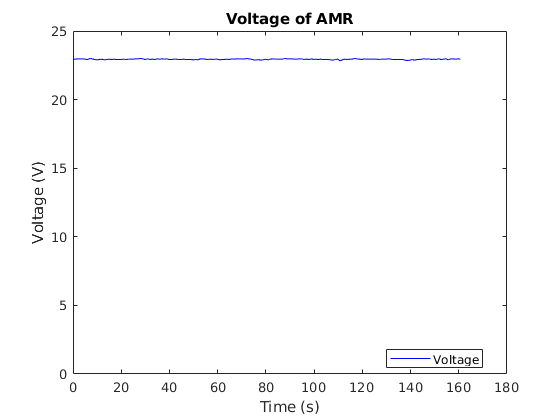

plot(voltageTime, voltage, '-b'); 
hold on
title('Voltage of AMR'); 
ylabel('Voltage (V)'); 
xlabel('Time (s)'); 
legend('Voltage', 'location', 'best');
ylim([0,25]); 
print(strcat(experimentString,'-Figures/', experimentString, '-Voltage-Plot'), '-depsc');
hold off

Plot current calculations

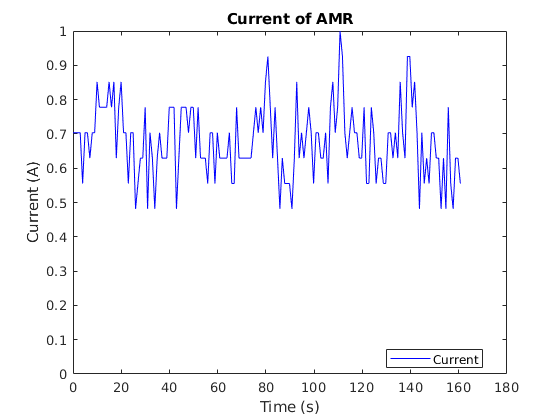

plot(currentTime, current, '-b'); 
hold on
title('Current of AMR'); 
ylabel('Current (A)'); 
xlabel('Time (s)'); 
legend('Current', 'location', 'best'); 
ylim([0,1]); 
print(strcat(experimentString,'-Figures/', experimentString, '-Current-Plot'), '-depsc');
hold off

Plot Wheel Encoder Data

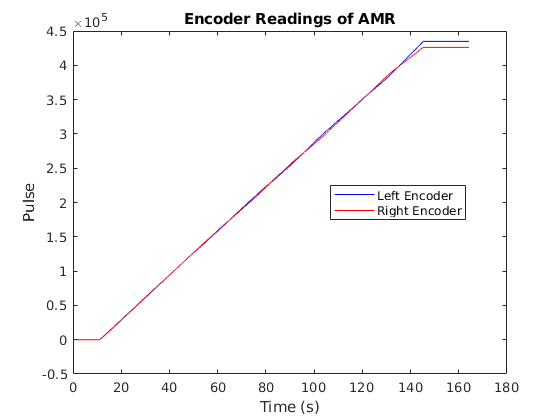

plot(encoderTime, leftEncoder, '-b');
hold on
title('Encoder Readings of AMR');
xlabel('Time (s)');
ylabel('Pulse');    
plot(encoderTime, rightEncoder, '-r');
legend('Left Encoder', 'Right Encoder', 'Location', 'best')
print(strcat(experimentString,'-Figures/', experimentString, '-Encoder-Plot'), '-depsc');
hold off

Plot Calculated RPM Data 

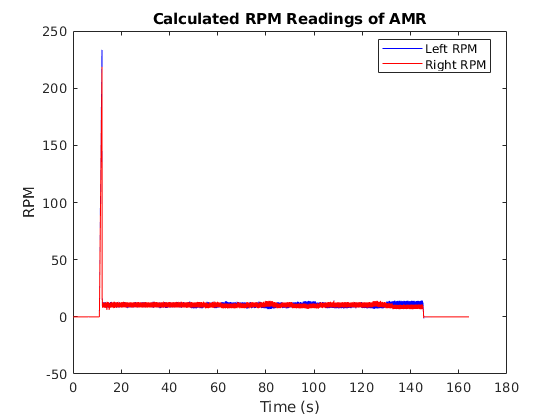

plot(encoderTime(2:end), calcLeftRPM, '-b');
hold on 
title('Calculated RPM Readings of AMR');
xlabel('Time (s)');
ylabel('RPM');
plot(encoderTime(2:end), calcRightRPM, '-r'); 
legend('Left RPM', 'Right RPM', 'Location', 'best')
print(strcat(experimentString,'-Figures/', experimentString, '-Calculated-RPM-Plot'), '-depsc');
hold off 

Plot Measured Encoder Data

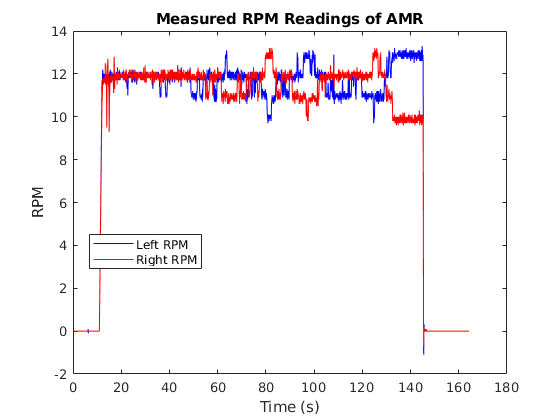

plot(encoderTime, leftRPM, '-b');
hold on
title('Measured RPM Readings of AMR');
xlabel('Time (s)');
ylabel('RPM');
plot(encoderTime, rightRPM, '-r');
legend('Left RPM', 'Right RPM', 'Location', 'best')
print(strcat(experimentString,'-Figures/', experimentString, '-Measured-RPM-Plot'), '-depsc');
hold off

Plot Robot Pose with Ground Truth 

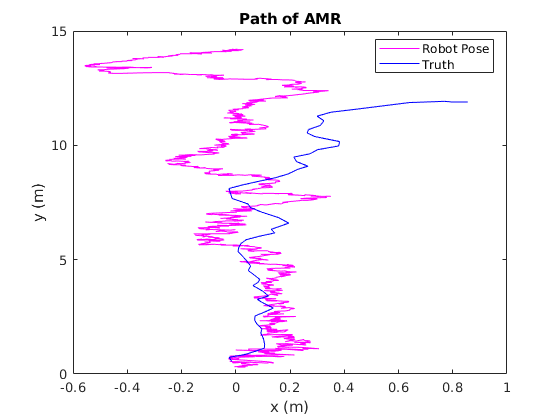

plot(robotPose(:,1), robotPose(:,2), '-m');
hold on
title('Path of AMR');
xlabel('x (m)');
ylabel('y (m)');
plot(truth(:,2), truth(:,3), '-b');
legend('Robot Pose', 'Truth', 'Location','best')
print(strcat(experimentString,'-Figures/', experimentString, '-Pose-Plot'), '-depsc');
hold off 

Plot Map Generated

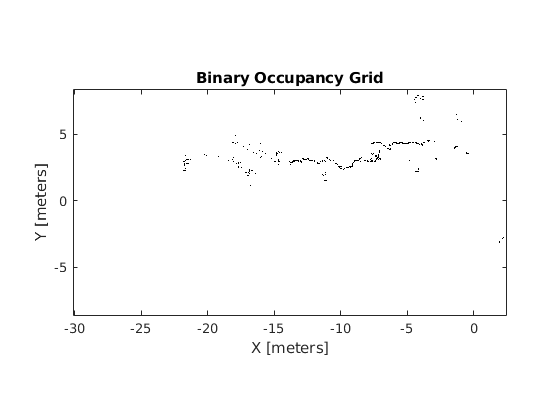

show(map);
print(strcat(experimentString,'-Figures/', experimentString, '-Map'), '-depsc');